reduced_ord_state_obsv;


=== Progetto Osservatore Ridotto ===
Polo osservatore λo = -215.83 rad/s
Guadagno osservatore L  = 182.1037

=== Verifica ===
Autovalore calcolato di Ao: -215.83 (deve essere -215.83)
Dimensioni: Ao(1x1), Bo(1x2), Co(2x1), Do(2x2) ✓


step_gain = 50;

T = 1e-3;

simOut_2_2_3_1ms = sim('Lab_2\Point_2_2\2_2_3\discrete_model.slx');

Found algebraic loop that contains: 
discrete_model/State-space controller/MatrixMultiply
discrete_model/State-space controller/Sum1
discrete_model/State-space controller/Saturation (discontinuity)
discrete_model/Discrete State-Space
discrete_model/State-space controller/rpm2rad//s
discrete_model/State-space controller/deg2rad(2)


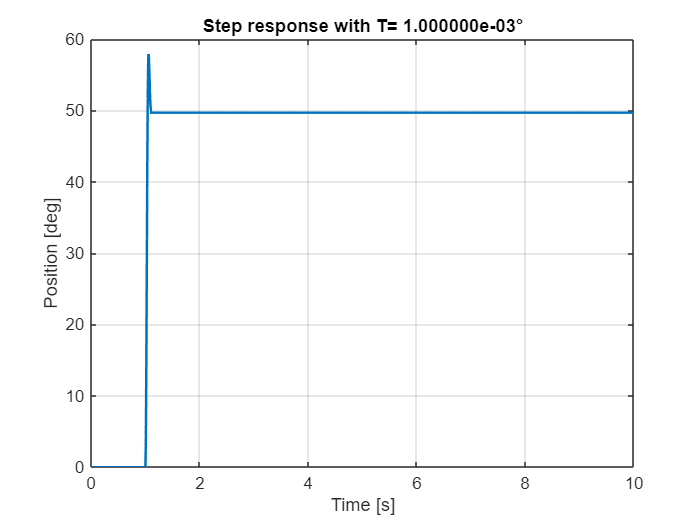


% Create plots
% Define the step amplitude vector

figure; 
plot(simOut_2_2_3_1ms.th.time,squeeze(simOut_2_2_3_1ms.th.signals.values), 'LineWidth', 1.5);
grid on;
title(sprintf('Step response with T= %d°', T));
xlabel('Time [s]');
ylabel('Position [deg]');

T = 10e-3;

simOut_2_2_3_10ms = sim('Lab_2\Point_2_2\2_2_3\discrete_model.slx');

Found algebraic loop that contains: 
discrete_model/State-space controller/MatrixMultiply
discrete_model/State-space controller/Sum1
discrete_model/State-space controller/Saturation (discontinuity)
discrete_model/Discrete State-Space
discrete_model/State-space controller/rpm2rad//s
discrete_model/State-space controller/deg2rad(2)


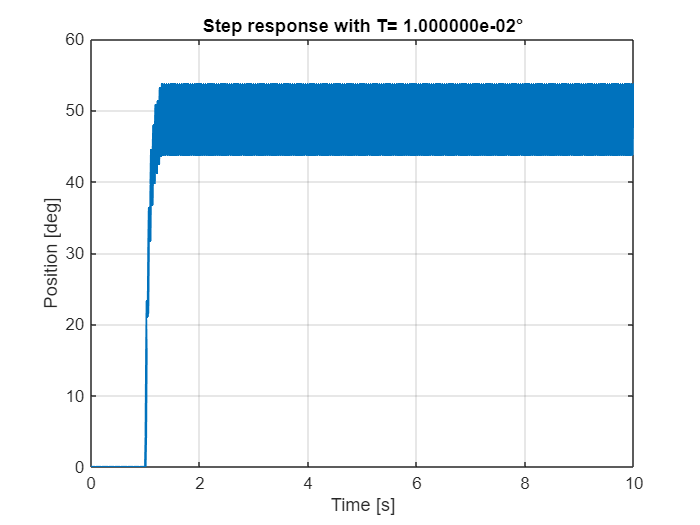


% Create plots
% Define the step amplitude vector

figure; 
plot(simOut_2_2_3_10ms.th.time,squeeze(simOut_2_2_3_10ms.th.signals.values), 'LineWidth', 1.5);
grid on;
title(sprintf('Step response with T= %d°', T));
xlabel('Time [s]');
ylabel('Position [deg]');



T = 50e-3;

simOut_2_2_3_50ms = sim('Lab_2\Point_2_2\2_2_3\discrete_model.slx');

Found algebraic loop that contains: 
discrete_model/State-space controller/MatrixMultiply
discrete_model/State-space controller/Sum1
discrete_model/State-space controller/Saturation (discontinuity)
discrete_model/Discrete State-Space
discrete_model/State-space controller/rpm2rad//s
discrete_model/State-space controller/deg2rad(2)


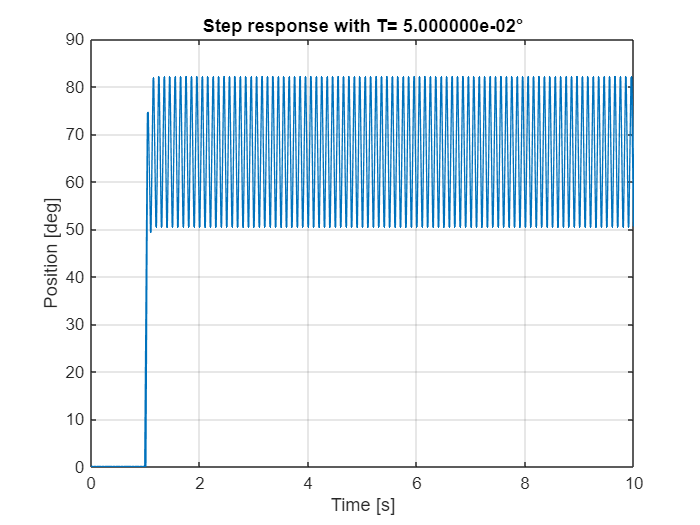


% Create plots
% Define the step amplitude vector

figure; 
plot(simOut_2_2_3_50ms.th.time,squeeze(simOut_2_2_3_50ms.th.signals.values), 'LineWidth', 1.5);
grid on;
title(sprintf('Step response with T= %d°', T));
xlabel('Time [s]');
ylabel('Position [deg]');